clear all;
clc;
load 2tx_x2_heltf160_withoutCP.mat;
data = read_complex_binary('/mnt/tmp/1031_x2_withoutCP_tx1tx2_d100_static.dat');
i = 4;
fs=200e6;
symbollen_table = [256, 512, 1024, 2048];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);
framelen=symbollen;
rawframe=cfg.userltf(1,:);


% 呼吸带数据1017_x2_withoutCP_tx1tx2_pmz2m_walk
huxi=csvread('/mnt/tmp/1031_x2_withCP_tx1tx2_d100_static2.csv',1,0);

% 
% % STO-CP相关
% 
% numfram=6000;
% for i=(numfram-10)*framelen+1:(numfram-1)*framelen
%     cp_win1=abs(data(i:i+gilen-1));
%     cp_win2=abs(data(i+symbollen:i+framelen-1));
%     findpoint(i)=(cp_win1-cp_win2)'*(cp_win1-cp_win2);
% end
% [~,sorted_indices]=sort(abs(findpoint),'ascend');
% % [~,oneposit1ion]=min(findpoint);onepositiononeposition

% 
% figure
% plot(abs(findpoint))

% 
% zzzz=find(findpoint<1);
% plot(diff(zzzz))

% 
% [~,oneposition]=min(findpoint);
% onedata=data(oneposition:end);
% test_onedata=onedata(1:floor(length(onedata)/framelen)*framelen);
% onecir=getcir(test_onedata,framelen,rawframe,gilen); 2tx_x2_heltf160

% 
% figure
% imagesc(abs(onecir));4
% title('cp相关cir')
% axis xy

% 
% [~,oneindex]=max(abs(onecir));
% figure
% plot(oneindex)
% 
% [~,one_sorted_cir]=sort(abs(onecir(:)),'descend');
% figure
% plot(one_sorted_cir)

## gaizhege

rawdata=data(1:end);% data sto_data

rawdata=rawdata(1:floor(length(rawdata)/framelen)*framelen);
cir1=getcir(rawdata,framelen,rawframe); 

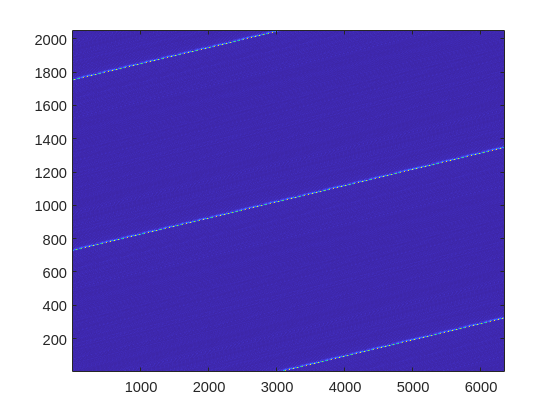

figure
imagesc(abs(cir1));
axis xy;

% numfram=10;
% for i=1:(numfram-1)*framelen
%     cp_win1=abs(data(i:i+gilen-1));
%     cp_win2=abs(data(i+symbollen:i+framelen-1));
%     findpoint(i)=(cp_win1-cp_win2)'*(cp_win1-cp_win2);
% end
% 
% [~,sorted_indices]=sort(abs(findpoint),'ascend');
% detacir=400;
% cir13=cir1;
% cir13=circshift(cir13,detacir,1);
% figure
% imagesc(abs(cir13));
% title('循环移位');
% axis xy;detasub

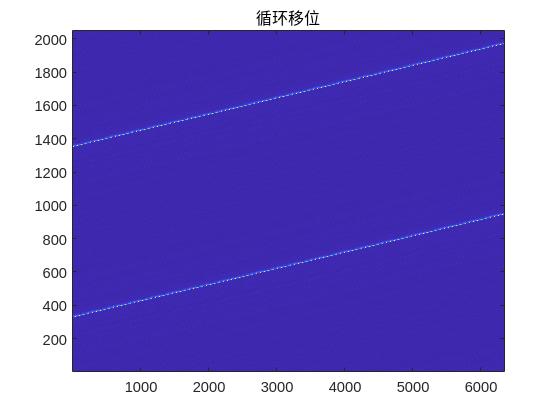

cir11=circshift(cir1,-400,1);
figure
imagesc(abs(cir11));
title('循环移位');
axis xy;

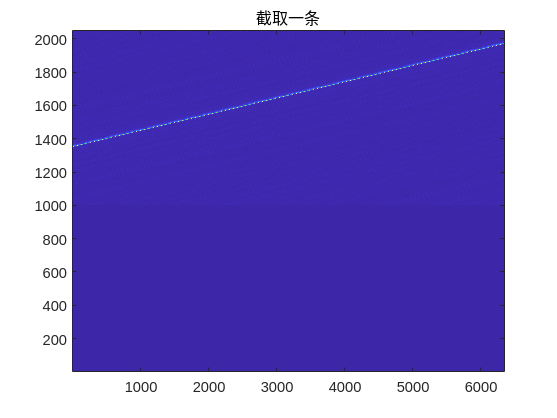


cir12=cir11;
% cir12(1:800,1:8000)=0;
cir12(1:1000,:)=0;
% cir12(1400:end,10000:14000)=0;
% cir12(800:end,14001:end)=0;

% cir12(1100:end,:)=0;
% cir12(1:200,:)=0;
figure
imagesc(abs(cir12));
title('截取一条')
axis xy

[value1,index1]=max(abs(cir12));2

ans = 2

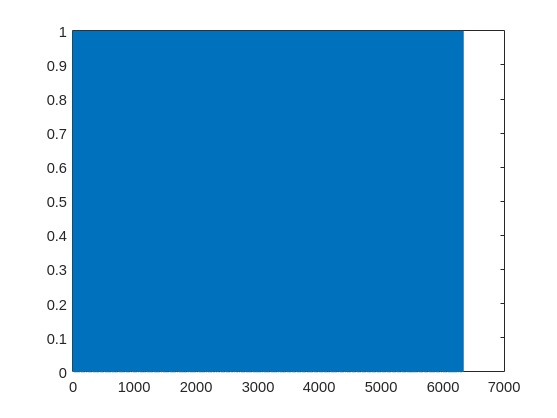


figure
plot(diff(index1(1:end-2)))

1

ans = 1

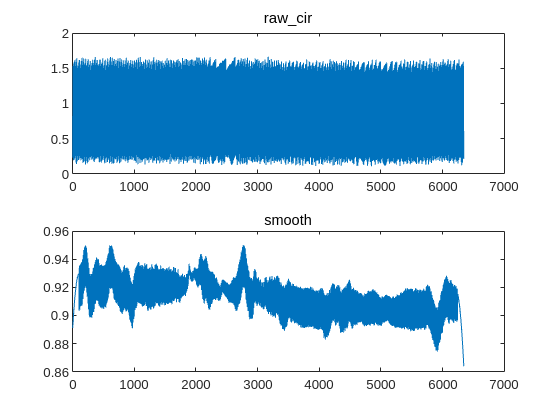

detasub=5;
for i=1:size(cir12,2)
    value2(i)=abs(cir12(index1(i)+detasub,i));
end
figure
subplot(2,1,1)
plot(value2);
title('raw\_cir');
subplot(2,1,2)
plot(smoothdata(value2,'sgolay',200));
title('smooth');

value3=lowpass(value2,0.000015);
% subplot(4,1,3)
% plot(value3);
% title('lowpass')
% subplot(4,1,4)
% plot(smoothdata(value3,'sgolay',1000));
% title('lowpass+smooth')

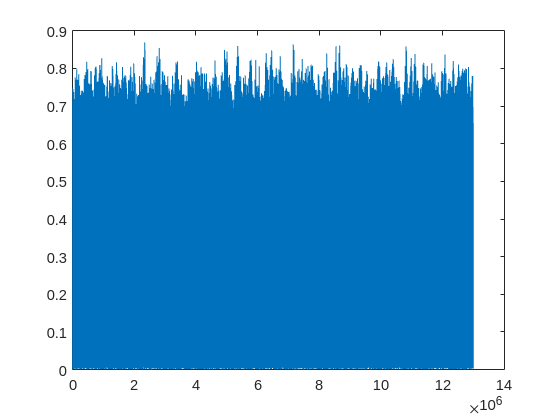

figure
plot(abs(data))

% detasub=-3;
% for i=1:size(cir12,2)
%     value2(i)=abs(cir12(index1(i)+detasub,i));
% end
% figure
% plot(smoothdata(value2,'sgolay',1000));
% title('smooth');

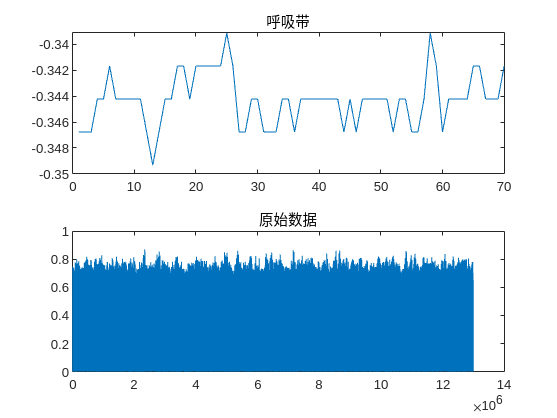



figure
subplot(2,1,1)
plot(huxi);
title('呼吸带')
subplot(2,1,2)
plot(abs(rawdata));
title('原始数据')


% smooth_data=smoothdata(value2,'sgolay',1000);
% [prmA1,prmB1]=butter(2,[0.05 0.25],'bandpass');
% butter_value=filter(prmA1,prmB1,smooth_data);
% figure
% subplot(2,1,1)
% plot(smooth_data);
% subplot(2,1,2)
% plot(butter_value);

% [imf,residual,info] = emd(butter_value);
% figure
% emd(butter_value);

% figure
% plot(smoothdata(max(abs(cir12)),'movmean',1000),'LineWidth',2,'Color','r');
% title('滤波后cir');
% set(gca,"Position",[.3,.2,.6,.4])

% figure
% plot(huxi,'LineWidth',2,'Color','r');
% title('呼吸带');
% set(gca,"Position",[.3,.2,.6,.4])

% cfr
% rawcfr_data=reshape(rawdata,framelen,length(rawdata)/framelen);
% rawcfr_data=fftshift(fft(rawcfr_data,[],1));
% % cfr_data=fftshift(cfr_data.*conj(rawframe)');
% cfr_phdata=unwrap(angle(rawcfr_data),[],2);

% figure
% plot(cfr_phdata(1,:),'LineWidth',1);
% hold on;
% plot(cfr_phdata(50,:),'LineWidth',1);
% hold on;
% plot(cfr_phdata(100,:),'LineWidth',1);
% hold on;
% plot(cfr_phdata(150,:),'LineWidth',1);
% hold on;
% plot(cfr_phdata(200,:),'LineWidth',1);
% legend('1','50','100','150','200');
% title('raw\_cfr子载波相位')

% figure
% plot(cfr_phdata(513,:),'LineWidth',1,'Color','r');
% hold on;
% plot(cfr_phdata(1537,:),'LineWidth',1,'Color','b');
% legend('513','1537');
% title('中心子载波相位')




